clear

## Run other scripts

% DATA_TYPE = 'lowSI'; % or 'highSI'
DATA_TYPE = 'highSI';
% MODEL_list = ["SVM", "ESN", "LSTM", "GRU"];
MODEL_list = ["ESN", "SVM", "LSTM", "GRU"];

% Model_Channel_state_thes;

if strcmp(DATA_TYPE, 'lowSI')
    load Workspace\Channel_state_thres_var\lowSI_fc=55.7.mat;
else
    load Workspace\Channel_state_thres_var\highSI_fc=55.7.mat;
end

% h_state_thres = h_state_thres(1:3:end);
% N_state = length(h_state_thres)-1;

for j = 1:length(MODEL_list)

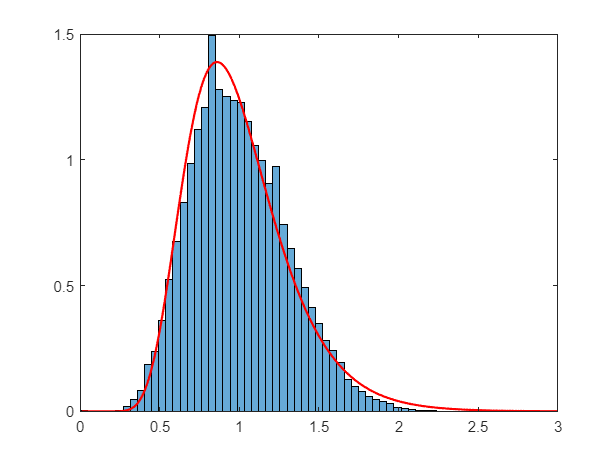

    MODEL = MODEL_list(j);

    Data_Proc_Import_predicted_data;

    Parameters_delay;

    Model_Atmospheric_turbulence;

    Model_AMP;

P_t = 2.0416

E_b_anal = 9.9999e+05

EE_anal = 4.8980e+08

P_t = 2.0416

E_b_anal = 9.9999e+05

EE_anal = 4.8980e+08

P_t = 2.0417

E_b_anal = 9.9999e+05

EE_anal = 4.8979e+08

P_t = 2.0417

E_b_anal = 9.9999e+05

EE_anal = 4.8979e+08

    Model_Channel_state_assignment;

    Model_AMP_subopt_state;

P_t = 2.0228

rate_anal = 9.7014e+08

EE_anal = 4.7959e+08

P_t = 2.0227

rate_anal = 9.7009e+08

EE_anal = 4.7960e+08

P_t = 2.0227

rate_anal = 9.7009e+08

EE_anal = 4.7960e+08

P_t = 2.0227

rate_anal = 9.7009e+08

EE_anal = 4.7960e+08


    % Model_AMP_predicted;
    Model_AMP_subopt_state_predicted;

energy_loss = 7.9074e-05

EE_predicted = 4.6831e+08

energy_loss = 7.8152e-05

EE_predicted = 4.6802e+08

energy_loss = 7.7283e-05

EE_predicted = 4.6881e+08

energy_loss = 7.6756e-05

EE_predicted = 4.6894e+08


    prob_BER_subopt_predicted(j) = prob_BER_exceeds_BERtar;

    EL_subopt_predicted(j) = energy_loss;
    
    EE_subopt_predicted(j) = EE_predicted;

end

# Plot the figures

## Set global configurations

set(groot, 'defaultLineMarkerSize', 25);
set(groot, 'DefaultLineLineWidth', 2);
set(groot, 'defaultAxesFontName', 'TimesNewRoman');
set(groot, 'defaultTextFontName', 'TimesNewRoman');
set(groot, 'defaultAxesFontSize', 12);
set(groot, 'defaultTextFontSize', 12);

# Low SI data type

if strcmp(DATA_TYPE, 'lowSI')

## Fig: Probability that $BER_{inst$ exceeds $BER_{tar$

    x_axis = categorical(MODEL_list);
    
    x_axis = reordercats(x_axis, ["ESN", "SVM", "LSTM", "GRU"]);
    
    y_axis = prob_BER_subopt_predicted;
    
    plot(x_axis, y_axis, '.-b', "DisplayName", '\sigma_R^2 = 0.0075')
        
    xlabel('Case')
    ylabel('Probability that BER_{inst} exceeds BER_{tar}')
    legend()
    grid on

## Fig: Energy loss

    y_axis = EL_subopt_predicted .* 1e3;
    
    plot(x_axis, y_axis, '.-b', "DisplayName", '\sigma_R^2 = 0.0075')
    
    xlabel('Case')
    ylabel('Energy Loss (mJ)')
    legend()
    grid on

## Fig: Energy Efficiency

    EE_subopt_predicted(1) = 4.523930066159852e+08;
    y_axis = EE_subopt_predicted;
    
%     semilogy(x_axis, y_axis, '.-b', "DisplayName", '\sigma_R^2 = 0.0075')
    bar(x_axis, y_axis, "DisplayName", '\sigma_R^2 = 0.0075')
    set(gca, 'YScale' , 'log' )
    
    xlabel('Case')
    ylabel('Energy Efficiency (Bits/Joule)')
    legend()
    grid on

end

# High SI data type

if strcmp(DATA_TYPE, 'highSI')

## Fig: Probability that $BER_{inst$ exceeds $BER_{tar$

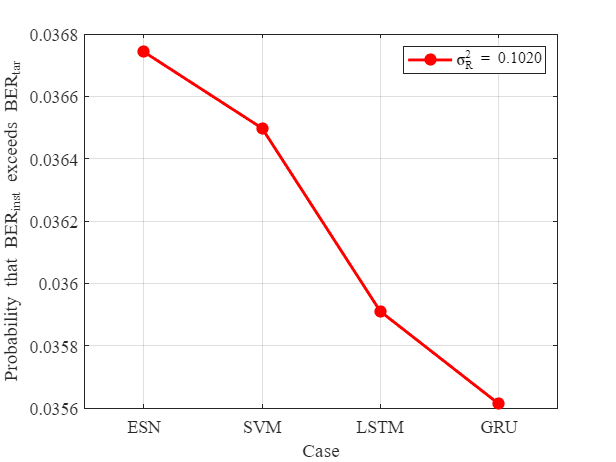

    x_axis = categorical(MODEL_list);
    
    x_axis = reordercats(x_axis, ["ESN", "SVM", "LSTM", "GRU"]);
    
    y_axis = prob_BER_subopt_predicted;
    
    plot(x_axis, y_axis, '.-r', "DisplayName", '\sigma_R^2 = 0.1020')
        
    xlabel('Case')
    ylabel('Probability that BER_{inst} exceeds BER_{tar}')
    legend()
    grid on

## Fig: Energy loss

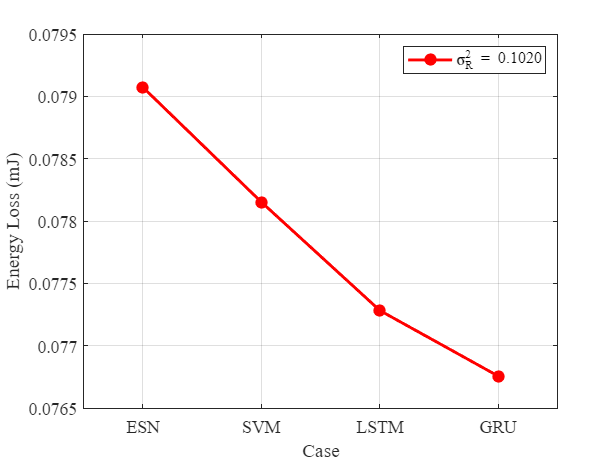

    y_axis = EL_subopt_predicted .* 1e3;
    
    plot(x_axis, y_axis, '.-r', "DisplayName", '\sigma_R^2 = 0.1020')
    
    xlabel('Case')
    ylabel('Energy Loss (mJ)')
    legend()
    grid on

## Fig: Energy Efficiency

    EE_subopt_predicted(3) = 4.689074566317422e+08

EE_subopt_predicted = 1.0e+08 *

    4.6831    4.6802    4.6891    4.6894


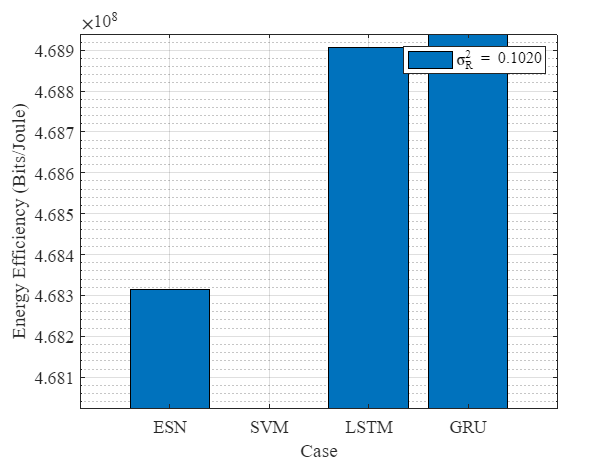

    y_axis = EE_subopt_predicted;
    
%     semilogy(x_axis, y_axis, '.-r', "DisplayName", '\sigma_R^2 = 0.1020')
    bar(x_axis, y_axis, "DisplayName", '\sigma_R^2 = 0.1020')
    set(gca, 'YScale' , 'log' )
    
    xlabel('Case')
    ylabel('Energy Efficiency (Bits/Joule)')
    legend()
    grid on

end

writematrix(EE_subopt_predicted, 'Workspace\Predicted_vs_delay\highSI.txt', 'Delimiter', '\t')